load("speechCommandModelv2.mat")

% Now taking own voice recording and predicting
recObj = audiorecorder(16000,16,1);

disp("Start speaking")

Start speaking


recordblocking(recObj,1);
disp("Recording finished")

Recording finished


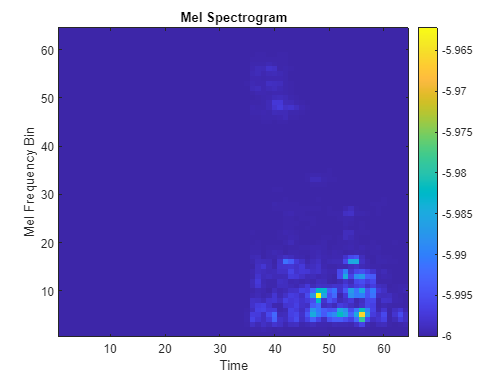


audio = getaudiodata(recObj);
audiowrite("testRecording.wav",audio,16000);

fs = 16000;
%playback
sound(audio,fs)

melSpec = melSpectrogram(audio, fs, 'NumBands',64);
melSpec = log10(melSpec + 1e-6);
melSpec = imresize(melSpec,[64 64]);

inputImage = reshape(melSpec,[64 64 1 1]);

figure;
imagesc(melSpec);
axis xy;
xlabel("Time");
ylabel("Mel Frequency Bin");
title("Mel Spectrogram");
colorbar;


[predictedWord, scores] = classify(net,inputImage);
disp("Predicted word: ");

Predicted word: 


disp(predictedWord)

     no 



maxScore = max(scores);
fprintf("Confidence: %.1f\n%%", maxScore*100);

Confidence: 30.3
%


if maxScore < 0.4
    disp("No command recognized")
else
    disp(predictedWord)
end

No command recognized
